%  ====== Find Nearest Neighbors  ======
% https://ww2.mathworks.cn/help/stats/knnsearch.html?s_tid=srchtitle_knnsearch_1

% Find the patients in the hospital data set that most closely resemble the patients in Y, 
% according to age and weight.

## Load the hospital data set.

load hospital;
X = [hospital.Age hospital.Weight];
Y = [20 162; 30 169; 40 168; 50 170; 60 171];   % New patients

## Perform a knnsearch between X and Y to find indices of nearest neighbors.

Idx = knnsearch(X,Y);
% Find the patients in X closest in age and weight to those in Y.

X(Idx,:)

ans =     25   171
    25   171
    39   164
    49   170
    50   172


## compare the results

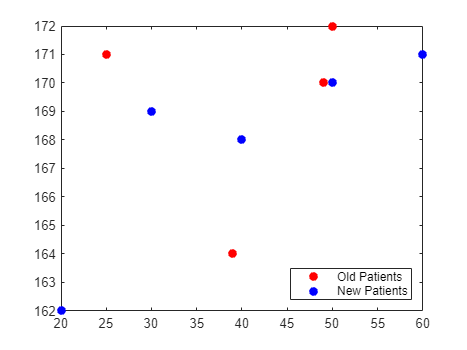

figure;
plot(X(Idx,1),X(Idx,2),'ro','MarkerFaceColor','r')
hold on;
plot(Y(:,1),Y(:,2),'bo','MarkerFaceColor','b')
legend('Old Patients','New Patients','Location','southeast')